clear all
clc
%% System Setup
Ts = 1/8000;  % Sampling time duration in seconds
Fs = 1/Ts; % Sampling frequency in Hz
T = 10; % Simulation time duration
t = 0:Ts:T-Ts; % sampled time

%% Carrier
Ac = 1; % Carrier amplitude
fc = 20; % Carrier frequency
ct = cos(2*pi*fc*t); % Carrier signal with amplitude 1
 
%% Message 
fm = 10; % Message frequency
A = 1.5; % Message amplitude
mt = square(2*fm*t);% Message signal with amplitude 1

Modulation

% PM Modulation
kp = 10; 
utpm = Ac*cos(2*pi*fc*t + kp*A*mt); 

% FM Modulation
kf = 0.75; 
utfm = Ac*cos(2*pi*fc*t + 2*pi*kf*A*cumsum(mt)); 

Plots :

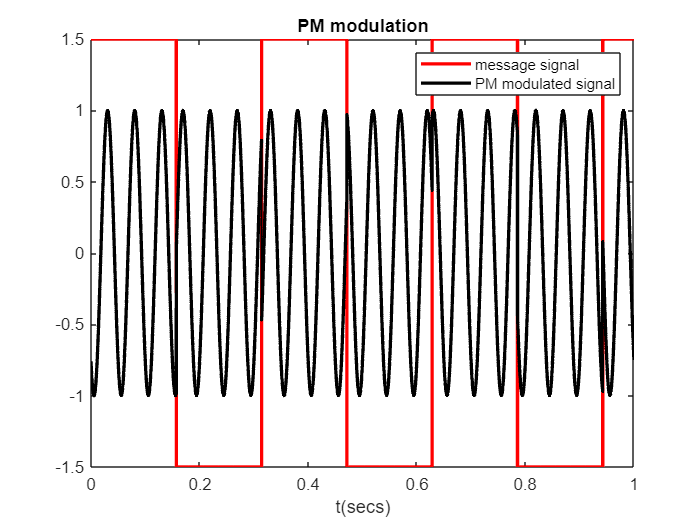

%% Plotting - Time Domain
hold off;  
plot(t(1:20/(Ts*fc)),A*mt(1:20/(Ts*fc)),'r','DisplayName','message signal','LineWidth',2); hold on;
plot(t(1:20/(Ts*fc)), utpm(1:20/(Ts*fc)),'k','DisplayName','PM modulated signal','LineWidth',2);
legend("show")
title("PM modulation")
xlabel("t(secs)")

hold off;  

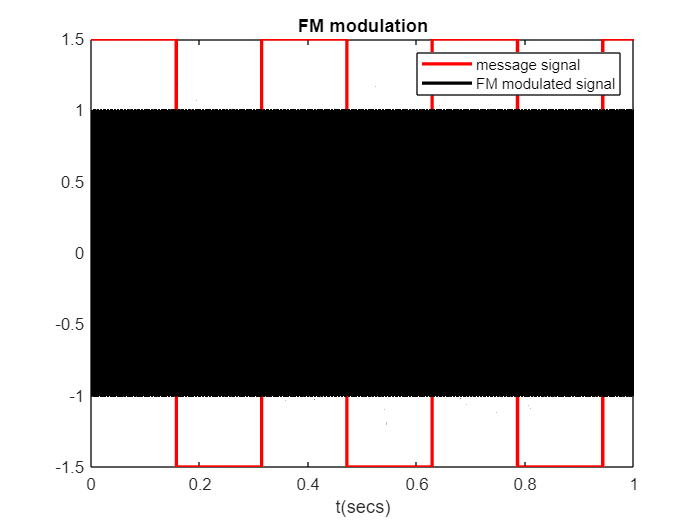

plot(t(1:20/(Ts*fc)),A*mt(1:20/(Ts*fc)),'r','DisplayName','message signal','LineWidth',2); hold on;
plot(t(1:20/(Ts*fc)), utfm(1:20/(Ts*fc)),'k','DisplayName','FM modulated signal','LineWidth',2);
legend("show")
title("FM modulation")
xlabel("t(secs)")

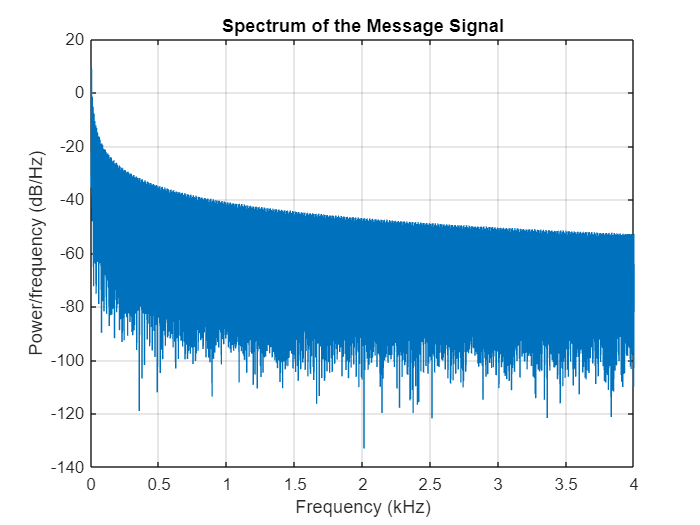


%% Plotting - Frequency Domain
Hs = spectrum.periodogram;
figure;
psd(Hs,mt,'Fs',Fs)
title('Spectrum of the Message Signal')

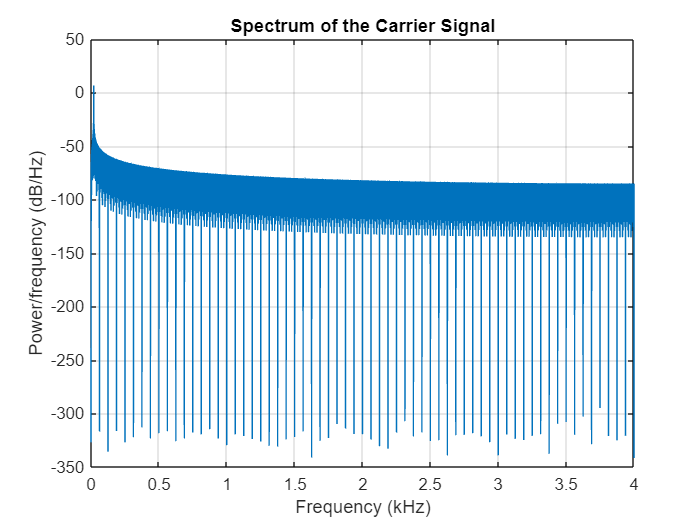


figure;
psd(Hs,ct,'Fs',Fs)
title('Spectrum of the Carrier Signal')

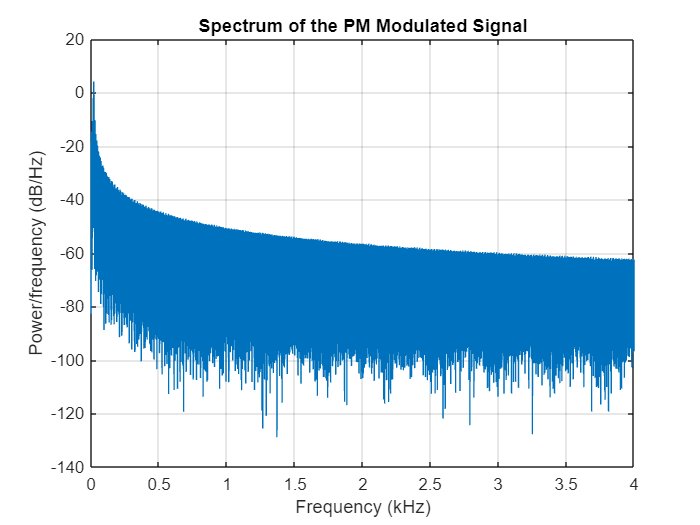


figure; 
psd(Hs,utpm,'Fs',Fs)
title('Spectrum of the PM Modulated Signal')

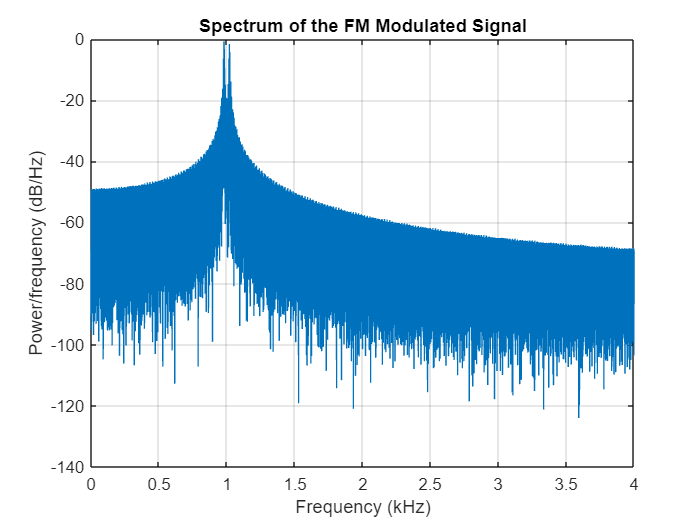


figure; 
psd(Hs,utfm,'Fs',Fs)
title('Spectrum of the FM Modulated Signal')

Demodulation:

1.For FM modulated wave :

This is done by Differentiation+Envelope Detection+DC shifting/scaling.

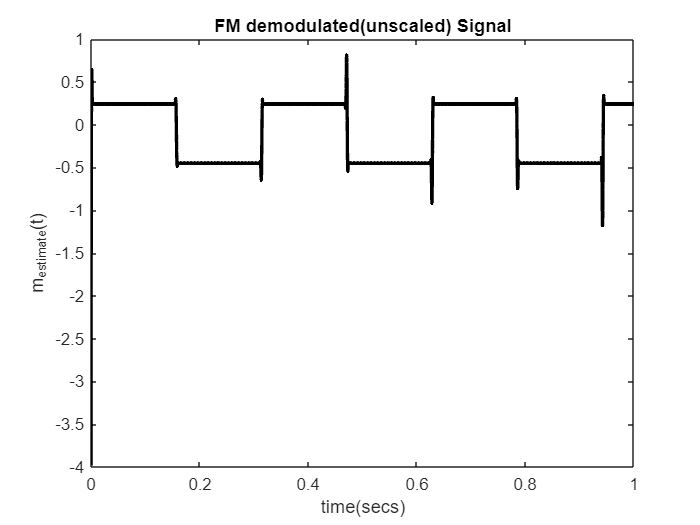

rtfm=utfm ;%%The received signal is assumed to be noise-free.
rtfmd=diff(utfm) ;
%%Envelope Detection:using squaring+low pass filtering+scaling)
rtfmsq=rtfmd.*rtfmd ;
rtfmf=lowpass(rtfmsq,1.2*fm,Fs) ; %%LPF
rtfms=sqrt(rtfmf/(2*pi*pi*Ac*Ac)) ;%%Unscaling and square rooting the envelope.
rtfmsc=rtfms-0.1225 ;%%Removing the DC shift.
mtest=(100*A).*rtfmsc ;%%Unscaling message in the envelope
plot(t(1:20/(Ts*fc)), mtest(1:20/(Ts*fc)) ,'k','DisplayName','FM demodulated signal','LineWidth',2);
title("FM demodulated(unscaled) Signal") ;
xlabel("time(secs)")
ylabel("m_{estimate}(t)")

2.For PM modulated wave :

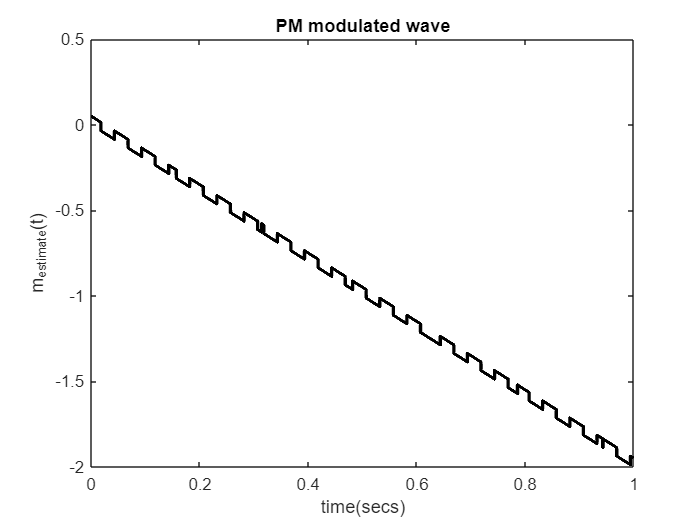

rtpm=utpm ;
rtphase=angle(rtpm) ;
rtsc=rtphase-(2*pi*fc*t) ;
mestimate=rtsc/(2*pi*kp) ;
plot(t(1:20/(Ts*fc)), mestimate(1:20/(Ts*fc)) ,'k','DisplayName','FM demodulated signal','LineWidth',2);
title("PM modulated wave")
xlabel("time(secs)")
ylabel("m_{estimate}(t)")

Observations :

1.The demodulation of FM signal was done using the limiter-discriminator approach.Overall output of the method was fairly as expected.However,it required choosing appropriate value of Kf.

2.The graph outline even if of correct shape still required shifting and scaling for some reason.

3.As for the PM signal,I attempted the demodulation as shown above but the graph was rotated.